# 1.主轴跟踪性能

## 确认LOG频率

故障未知仿真log的unknown_logger频率是50Hz

这里替换log中的时间采用相对时间

clear
clc
 
ulogOBJ = ulogreader("log_0_2021-6-30-08-07-24.ulg");
msg = readTopicMsgs(ulogOBJ);

## 确定unknown_logger的序号，提取log数据

更换log文件后需要修改下面的数值，找到msg中对应的unknown_logger的序号是多少。

 
% 获取unknown_logger数据
logSampleRate = 50;
unknown_logger = msg.TopicMessages{32};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取具体数据
h1 = unknown_logger.h1;
h2 = unknown_logger.h2;
h1d = unknown_logger.h1d;
h2d = unknown_logger.h2d;
uest = unknown_logger.uest;
uref = unknown_logger.uref;
chvDes = unknown_logger.chvdes;
tDes = unknown_logger.tdes;
psi = unknown_logger.psi;

## 1.1 画出主轴的跟踪图

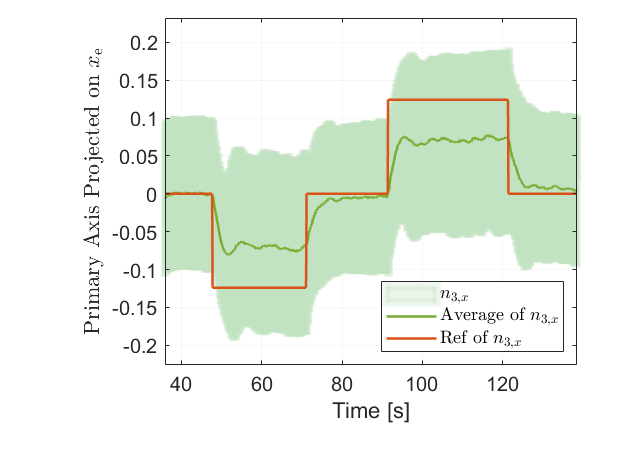

 

% 进行滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',50);
h1f = filtfilt(d,double(h1));
% 滤波出图
s = figure(3);
s.Position(4) = 10;
clf
area(relativeTime,h1,'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5)
hold on
plot(relativeTime,h1f,'Color','#77AC30','LineWidth',1.5)
plot(relativeTime,h1d,'Color','#D95319','LineWidth',1.5)

legend('$n_{3,x}$','Average of $n_{3,x}$','Ref of $n_{3,x}$',"Interpreter","latex",'Location',"best")
xlabel("Time [s]")
ylabel("Primary Axis Projected on $x_{\mathrm{e}}$","Interpreter","latex")

xlim([36.0 138.4])
ylim([-0.226 0.232])


% legend('Box',"off")

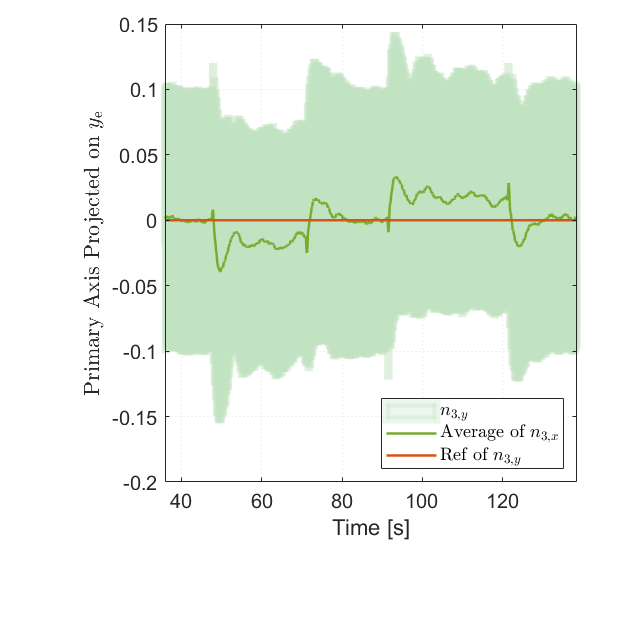

 

% 进行滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',50);
h2f = filtfilt(d,double(h2));
% 滤波出图
figure(3)
clf
area(relativeTime,h2,'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5)
hold on
plot(relativeTime,h2f,'Color','#77AC30','LineWidth',1.5)
plot(relativeTime,h2d,'Color','#D95319','LineWidth',1.5)

legend('$n_{3,y}$','Average of $n_{3,x}$','Ref of $n_{3,y}$',"Interpreter","latex")
xlabel("Time [s]")
ylabel("Primary Axis Projected on $y_{\mathrm{e}}$","Interpreter","latex")
xlim([36.0 138.4])

## 1.2 机体方位角和主轴的关系曲线

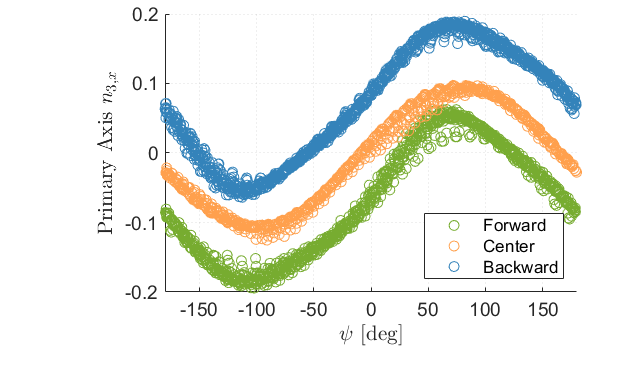

 
s = figure(7);
s.Position(4) = 8;
clf
% 设置显示的时间区间
tstart = 50;%采样开始时间
tend = 70;%采样结束时间
samplevector = tstart*logSampleRate:tend*logSampleRate;
scatter(psi(samplevector)*180/pi,h1(samplevector),'MarkerEdgeColor',"#77AC30")
hold on

tstart = 74;%采样开始时间
tend = 88;%采样结束时间
samplevector = tstart*logSampleRate:tend*logSampleRate;
scatter(psi(samplevector)*180/pi,h1(samplevector),'MarkerEdgeColor',"#ffa04d")
hold on

tstart = 94;%采样开始时间
tend = 117;%采样结束时间
samplevector = tstart*logSampleRate:tend*logSampleRate;
scatter(psi(samplevector)*180/pi,h1(samplevector),'MarkerEdgeColor',"#3483ba")
hold on

xlim([-180,180])
xlabel("$\psi$ [deg]","Interpreter","latex")
ylabel("Primary Axis $n_{3,x}$",'Interpreter',"latex")
legend("Forward","Center","Backward",'Location',"best")

上图中出现了三条连贯曲线, 最中间一条线代表遥控器摇杆居中的情况. 上侧分布代表遥控器摇杆发出后飞指令, 飞行器Z轴产生在地球坐标系上的正向分量, 反之下面的带状集中分布点代表飞机前飞指令下的机体Z轴在地球坐标系下的投影规律.从三条分布带的趋势来看

## 1.3 电机补偿环节跟踪图(数据源自控制器, 电机模型里不包括电机故障信息,所以以下数据可能需要额外的处理,例如加上电机失效系数)

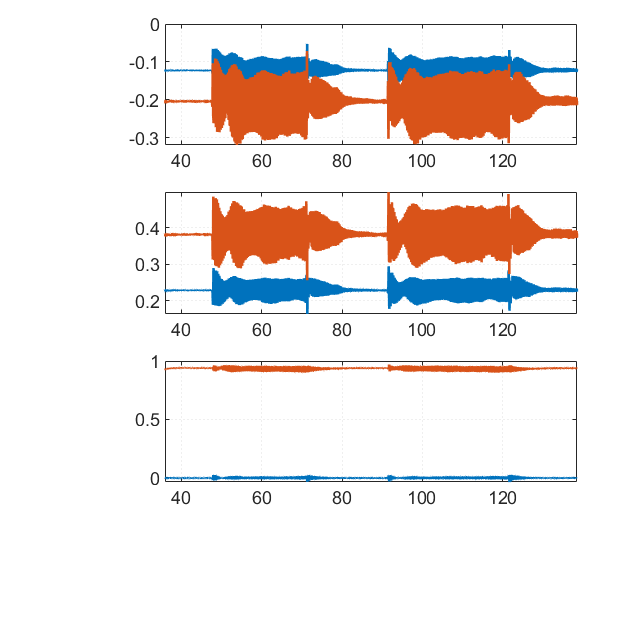

 

figure(4)
clf
subplot(3,1,1)
plot(relativeTime,uest(:,1),relativeTime,uref(:,1))
xlim([36.0 138.4])

subplot(3,1,2)
plot(relativeTime,uest(:,2),relativeTime,uref(:,2))
xlim([36.0 138.4])

subplot(3,1,3)
plot(relativeTime,uest(:,3),relativeTime,uref(:,3))
xlim([36.0 138.4])

# 2.机体的实际旋转轴估算(采用vehicle_attitude消息的数据)

clear
clc
 
ulogOBJ = ulogreader("log_0_2021-6-30-08-07-24.ulg");
msg = readTopicMsgs(ulogOBJ);

## 2.1 机体旋转轴在机体系下的坐标（注意区分旋转轴和主轴）

在High-Speed的文章中，其定义的主轴就是其旋转轴。而我们的方案是机体Z轴是主轴，旋转轴是不指定的（这样可能会导致控制效率底下）

 
% 姿态角,找到"vehicle_attitude"的序号四元数对应的旋转矩阵是R_{\mathrm{eb}}
vehicle_attitude = msg.TopicMessages{35};
logSampleRate = 20;
% 获取相对时间
log_time = vehicle_attitude.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 得到yaw为0的(无旋转的)旋转矩阵,并根据此得出机体旋转轴,相对的也可以理解为是地球坐标系的向量投射到机体系(无旋转)
% 左前方旋翼失效,俯仰角应该小于0, 横滚角应该大于0, 然而,根据RflySim3D显示和数显表明, 此时的横滚俯仰角均大于0!
quate = vehicle_attitude.q;
quate(:,1) = quate(:,1);
[vehicle_attitude_psi, pitch, roll] = quat2angle(quate);%该矩阵可以将地球坐标系下的向量投射到机体坐标系,反之是将向量旋转-roll和-pitch
% 计算倾斜矩阵(无旋转)(e-->b)
yaw = zeros(sample_count,1);
angle = angle2dcm(yaw,pitch,roll);

% 利用倾斜矩阵计算旋转轴
rotation_axis = zeros(sample_count,3);
for i=1:sample_count
    rotation_axis(i,:) = angle(:,:,i)*[0,0,1]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2.5,'SampleRate',20);
rotation_axis_xf = filtfilt(d,double(rotation_axis(:,1)));
rotation_axis_yf = filtfilt(d,double(rotation_axis(:,2)));
rotation_axis_zf = filtfilt(d,double(rotation_axis(:,3)));

%% 绘图
s = figure(1)

s =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 13.2000 8]
       Units: 'centimeters'

  显示 所有属性


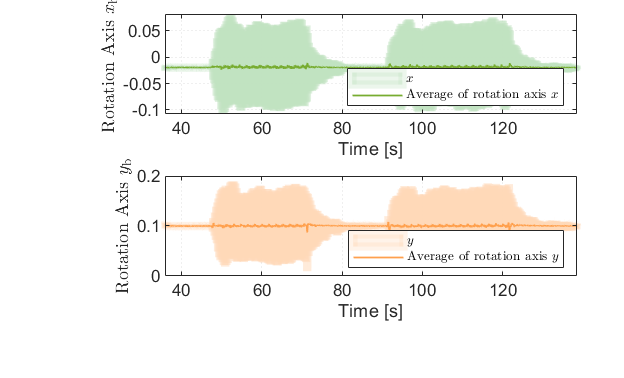

s.Position(4) = 8.0;
clf
subplot(2,1,1)
area(relativeTime,rotation_axis(:,1),'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,'BaseValue',-0.02)
hold on
plot(relativeTime,rotation_axis_xf,'LineWidth',1,'Color','#77AC30')
xlim([36.0 138.4])
xlabel("Time [s]")
ylabel("Rotation Axis $x_{\mathrm{b}}$","Interpreter","latex")
legend('$x$','Average of rotation axis $x$',"Interpreter","latex",'Location',"best")
legend('Box',"on",'FontSize',8)

subplot(2,1,2)
area(relativeTime,rotation_axis(:,2),'FaceColor','#ffd8b7','EdgeColor','#ffd8b7','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,"BaseValue",0.1)
hold on
plot(relativeTime,rotation_axis_yf,'LineWidth',1,'Color','#ffa04d')
xlim([36.0 138.4])
xlabel("Time [s]")
ylabel("Rotation Axis $y_{\mathrm{b}}$","Interpreter","latex")
legend('$y$','Average of rotation axis $y$',"Interpreter","latex",'Location',"best")
legend('Box',"on",'FontSize',8)


% subplot(3,1,3)
% area(relativeTime,rotation_axis(:,3),'FaceColor','#bcd6e8','EdgeColor','#bcd6e8','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,"BaseValue",0.995)
% hold on
% plot(relativeTime,rotation_axis_zf,'LineWidth',1,'Color','#3483ba')
% xlim([36.0 138.4])
% xlabel("Time [s]")
% ylabel("Rotation Axis $z_{\mathrm{b}}$","Interpreter","latex")
% legend('$z$','Average of rotation axis $z$',"Interpreter","latex",'Location',"best")
% legend('Box',"on",'FontSize',8)

## 2.2 机体旋转轴在地球坐标系下的坐标（注意区分旋转轴和主轴）

根据前面的部分可知, 机体的旋转轴在机体系下的坐标大致为[-0.02  0.1 0.9948]

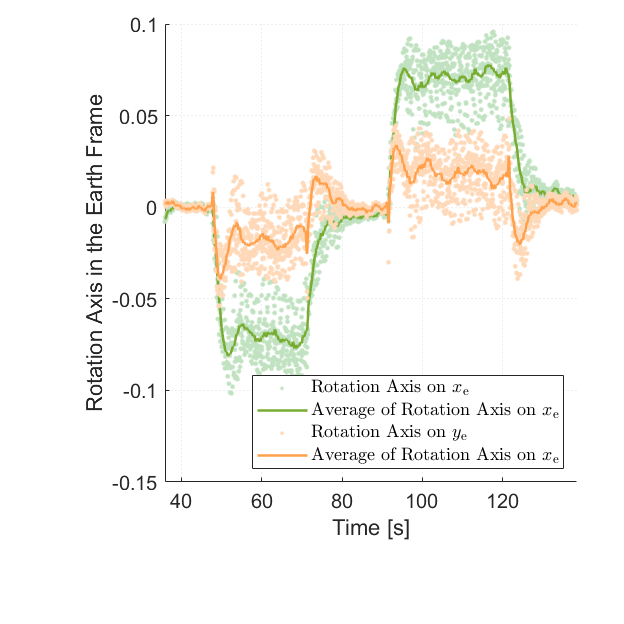

% 将四元数转换为旋转矩阵
vehicle_attitude_dcm = quat2dcm(quate);
% 利用旋转矩阵, 将估算出的机体旋转轴映射到地球坐标系中(旋转矩阵的顺序应该是将向量从及体系到地球系的转换即b-->e,而这里得出的矩阵是e-->b, 因此需要对矩阵进行转置)
rotation_axis_e = zeros(sample_count,3);
for i=1:sample_count
    rotation_axis_e(i,:) = vehicle_attitude_dcm(:,:,i)'*[-0.02  0.1 0.9948]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',20);
rotation_axis_e_xf = filtfilt(d,double(rotation_axis_e(:,1)));
rotation_axis_e_yf = filtfilt(d,double(rotation_axis_e(:,2)));
rotation_axis_e_zf = filtfilt(d,double(rotation_axis_e(:,3)));
% 绘制图像
figure(9)
% 滤波前的旋转轴在地球坐标系下的投影
clf
scatter(relativeTime,rotation_axis_e(:,1),72,'.','MarkerEdgeColor',"#c0e2c0","MarkerFaceColor","#c0e2c0","MarkerEdgeAlpha",0.3,"MarkerFaceAlpha",0.3)
hold on
plot(relativeTime,rotation_axis_e_xf,'Color','#77AC30','LineWidth',1.5)
hold on
scatter(relativeTime,rotation_axis_e(:,2),72,'.','MarkerEdgeColor',"#ffd8b7","MarkerFaceColor","#ffd8b7","MarkerEdgeAlpha",0.3,"MarkerFaceAlpha",0.3)
hold on
plot(relativeTime,rotation_axis_e_yf,'Color','#ffa04d','LineWidth',1.5)
% plot(relativeTime,rotation_axis_e(:,1:2))
xlim([36.0 138.4])
xlabel("Time [s]")
ylabel("Rotation Axis in the Earth Frame")
legend("Rotation Axis on $x_\mathrm{e}$","Average of Rotation Axis on $x_\mathrm{e}$","Rotation Axis on $y_\mathrm{e}$","Average of Rotation Axis on $x_\mathrm{e}$","Interpreter","latex",'Location',"best")

## 2.3 机体旋转轴与机体方位角的关系(半成品)

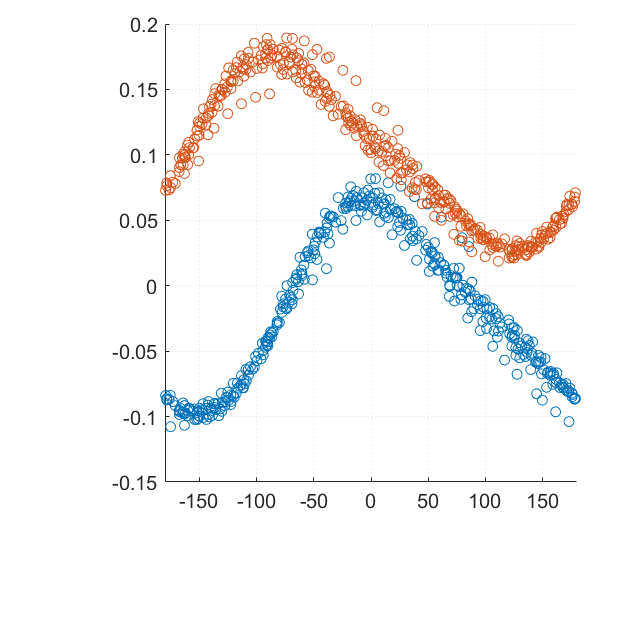

% 这部分的纵轴与2.1部分一致, 只是横轴变成了方位角
figure(8)
clf
tstart = 50;%采样开始时间
tend = 70;  %采样结束时间
samplevector = tstart*logSampleRate:tend*logSampleRate;
scatter(vehicle_attitude_psi(samplevector)*180/pi,rotation_axis(samplevector,1))
hold on
scatter(vehicle_attitude_psi(samplevector)*180/pi,rotation_axis(samplevector,2))
xlim([-180, 180])

% hold on
% scatter(vehicle_attitude_psi(samplevector)*180/pi,rotation_axis(samplevector,3))

# 3.位置环(向北飞行)下方位角与电机转速的关系(归一化?)

这部分与前面部分无关系，使用单独的log文件

进行单独前飞位置环的HIL仿真，画出方位角与电机转速的关系图（只有姿态环的话效果不好。）

 
clear
clc
ulogOBJ = ulogreader("log_2_2021-6-30-08-31-52.ulg");
msg = readTopicMsgs(ulogOBJ);

 
% 获取unknown_logger数据
logSampleRate = 50;
unknown_logger = msg.TopicMessages{28};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取具体数据
% h1 = unknown_logger.h1;
% h2 = unknown_logger.h2;
% h1d = unknown_logger.h1d;
% h2d = unknown_logger.h2d;
% uest = unknown_logger.uest;
% uref = unknown_logger.uref;
% chvDes = unknown_logger.chvdes;
tDes = unknown_logger.tdes;
psi = unknown_logger.psi;

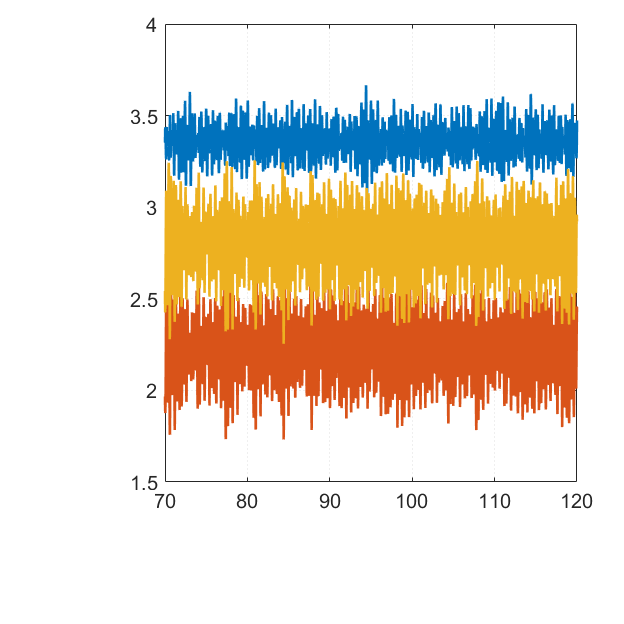

 
% 控制器输出的电机的期望的拉力

% 设置显示的时间区间
tstart = 70;%采样开始时间
tend = 120;%采样结束时间

figure(5)
%展示时间-电机拉力的关系
clf
plot(relativeTime,tDes(:,1),relativeTime,tDes(:,2),relativeTime,tDes(:,4))
xlim([tstart,tend])

## 3.1 电机拉力与方位角的关系

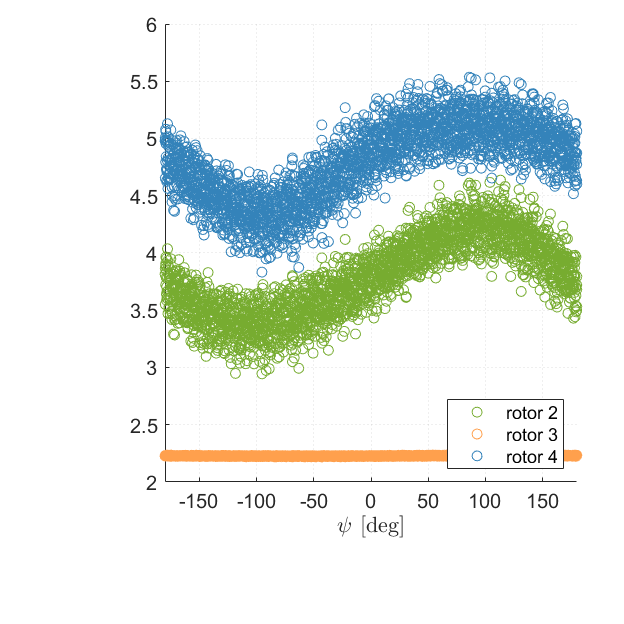

clf
%指定数据区域
samplevector = tstart*logSampleRate:tend*logSampleRate;
%绘制图像
% scatter(psi(samplevector)*180/pi,tDes(samplevector,1)/5*8.5)
% hold on
scatter(psi(samplevector)*180/pi,tDes(samplevector,2)/5*8.5,'MarkerEdgeColor','#77AC30')
hold on
scatter(psi(samplevector)*180/pi,tDes(samplevector,3)/5*8.5,'MarkerEdgeColor','#ffa04d')
hold on
scatter(psi(samplevector)*180/pi,tDes(samplevector,4)/5*8.5,'MarkerEdgeColor','#3483ba')
legend("rotor 2","rotor 3","rotor 4",'Location',"best")
xlim([-180,180])
xlabel("$\psi$ [deg]",'Interpreter',"latex")

## 3.2 力矩与方位角度的关系

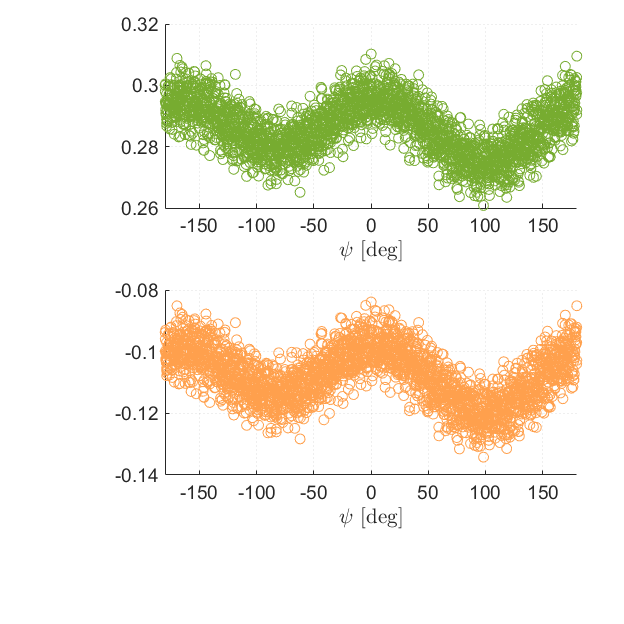

 
% 力矩与方位角度的关系
% 选取和HIL中模型一致的控制分配矩阵参数
c  = (0.0166);
l  = (0.125);
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);
% 获取虚拟控制通道向量,即总的拉力和三个轴的力矩
v = zeros(sample_count,4);
for i = 1:sample_count
    v(i,:) = M*((tDes(i,:)/5*8.5)'.*[0,1,1,1]');
end
% 绘制图像
figure(6)
clf
% scatter(psi(samplevector)*180/pi,v(samplevector,1))
% hold on
subplot(2,1,1)
scatter(psi(samplevector)*180/pi,v(samplevector,2),'MarkerEdgeColor',"#77AC30")
xlim([-180,180])
xlabel("$\psi$ [deg]",'Interpreter',"latex")

subplot(2,1,2)
scatter(psi(samplevector)*180/pi,v(samplevector,3),'MarkerEdgeColor',"#ffa04d")
xlim([-180,180])
xlabel("$\psi$ [deg]",'Interpreter',"latex")